% Coefficients
N = 20;
y0 = 100

y0 = 100

LSE_order = 2

LSE_order = 2

coeffs = [0.5 0.05]'

coeffs =     0.5000
    0.0500


zero_noise = zeros(1, N);

% Generate the actual system
noise_samples = generate_noise(N);
output_samples = generate_AR_output(N, y0, coeffs, noise_samples)

output_samples =   100.2145    5.2166    8.3547    4.0781    1.5193    1.1894    0.3385    0.8054    0.7699    0.7036    1.0938    0.5925    0.5594    0.1462    0.9520    0.8250    0.0686    0.2157   -0.2765   -0.8642



% Predict LSE of system
theta_lse = calculate_least_squares(LSE_order, N, output_samples)

theta_lse =     0.0553
    0.0833


predicted_output_samples = generate_AR_output(N, y0, theta_lse, zero_noise)

predicted_output_samples =   100.0000    8.3332    8.7940    1.1807    0.7981    0.1425    0.0744    0.0160    0.0071    0.0017    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


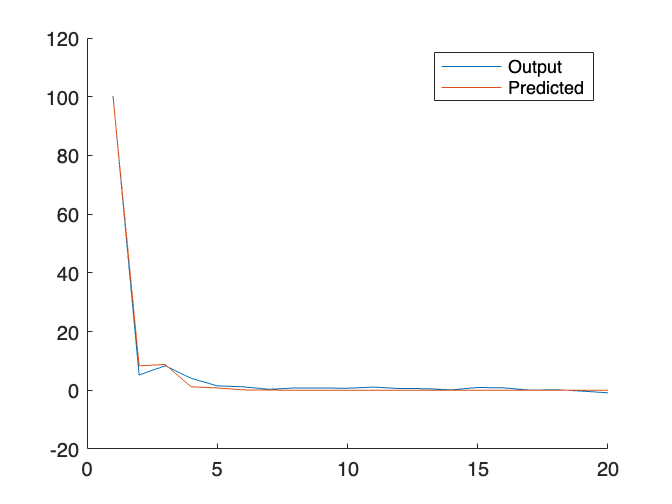



% Plot output
figure 
hold on
plot(output_samples)
plot(predicted_output_samples)
legend('Output', 'Predicted')
hold off


phi_indices = get_phi_index(10, length(coeffs))

phi_indices =      9     8


phi = get_phi(output_samples, phi_indices)

phi =     0.7699
    0.8054


phi' * theta_lse

ans = 0.1097

output_samples(10)

ans = 0.7036


% SPS initialisation



p = 0.8500



% Generate the random permutation pi 
% TODO: Use this in the sorting of the SPS algorithm
% pi_perm = randperm(m)-1




% Calculate SPS Indicators
test_theta = [0.6; 0.1]

test_theta =     0.6000
    0.1000


p = 0.1 % Probability requirement for confidence region between 0 and 1

p = 0.1000


result = test_theta_in_confidence_region(output_samples, test_theta, p)

result = logical
   0



% n_trials = 1000
% results = zeros(1, n_trials);
% 
% for i = 1:n_trials
%     % if mod(i, 1000) == 0
%     %     disp(i)
%     % end
% 
%     results(i) = test_theta_in_confidence_region(output_samples, test_theta, p);
% end
% 
% results

% sum(results) / n_trials



% SPS Algorithms
function in_region = test_theta_in_confidence_region(output_samples, test_theta, p)
    [q m] = rat(1-p);
    

    % q = 3*q;
    % m = 3*q;

    % Generate array of random signs
    signs = zeros(m-1, length(output_samples));
    for i = 1:m-1
        signs(i, :) = generate_random_signs(length(output_samples));
    end


    indicators = zeros(1, m);
    
    % Baseline
    baseline = calculate_sps_indicator(output_samples, ones(1, length(output_samples)), test_theta);
    indicators(1) = baseline;
    
    % Calculate m-1 indicators
    for i = 1:m-1
        indicators(i+1) = calculate_sps_indicator(output_samples, signs(i,:), test_theta);
    end
    
    % Order the indicators and find the rank of the baseline
    sorted = sort(indicators);
    rank = find(sorted == indicators(1));
    
    in_region = rank <= m - q;
end

function sps_indicator = calculate_sps_indicator(output_samples, signs, theta)
    order = length(theta);
    prediction_errors = calculate_prediction_error(output_samples, theta);

    Rn = calculate_outer_product(output_samples, order);
    root_Rn = chol(Rn);

    phi_t = get_phi_matrix(output_samples, order);
    summed_output = zeros(order, 1);

    for i = 1:length(output_samples)
        summed_output = summed_output + signs(i) * phi_t(:,i) * prediction_errors(i);
    end

    normalised_sum = summed_output / length(output_samples);
    result = root_Rn^-1 * normalised_sum;
    sps_indicator = result' * result;
end


function prediction_errors = calculate_prediction_error(output_samples, theta)
    predicted_output_samples = generate_AR_output(length(output_samples), output_samples(1), theta, zeros(1, length(output_samples)));

    prediction_errors = output_samples - predicted_output_samples;
end


% Get the full phi vector with each column representing a time index
function phi_t = get_phi_matrix(output_samples, order)
    phi_t = zeros(order, length(output_samples));

    for i = 1:length(output_samples)
        phi_indices = get_phi_index(i, order);
        phi_t(:, i) = get_phi(output_samples, phi_indices);
    end
end

% Gets the values to lookup from the output samples y(t)
function phi_index = get_phi_index(t, order)
    phi_index = flip(arrayfun(@(x) x-order, t:t+order-1));
end


function Rn = calculate_outer_product(output_samples, order)
    n = length(output_samples);
    Rn = zeros(order);

    for i = 1:n
        phi = get_phi(output_samples, get_phi_index(i, order));
        Rn = Rn + phi*phi';
    end

    Rn = Rn / n;

end

% Fetch the relevant values as a vector from the output samples
function phi = get_phi(samples, phi_indices)
    phi = zeros(1, length(phi_indices));
    
    for i = 1:length(phi_indices)
        if phi_indices(i) < 1
            phi(i) = 0;
        else
            phi(i) = samples(phi_indices(i));
        end
    end

    % Return column vector
    phi = phi';
end


% Generate random signs
function random_signs = generate_random_signs(n_signs)
    random_signs = arrayfun( @(x) sign(randn()), 1:n_signs);
end


% Generate noise samples with uniform distribution between -1 and 1
function noise_samples = generate_noise(n_samples)
    noise_samples = arrayfun( @(x) 1-2*rand(), 1:n_samples);
end


% AR System
function output_samples = generate_AR_output(n_samples, y0, coeffs, noise_samples)
    order = length(coeffs);
    output_samples = zeros(1, n_samples);

    output_samples(1) = y0 + noise_samples(1);

    % Calculate vector for dot product
    for i = 2:n_samples
        samples = zeros(1, order);
        if i <= order
            samples(1: i-1) = output_samples(1:i-1);
        else
            samples = output_samples(i-order : i-1);
        end

        samples = flip(samples);
        output_samples(i) = samples * coeffs + noise_samples(i);
    end
end


% Calculate least squares for AR model (without noise)
function least_squares_estimate = calculate_least_squares(order, n_samples, output_samples)
    A = zeros(order);
    B = zeros(order, 1);

    for i = 1:n_samples
        % Build the phi matrix
        phi = zeros(order, 1);
        for j = 1:order
            if j >= i
                phi(j) = 0;
            else
                phi(j) = output_samples(i - j);
            end
        end

        A = A + phi * phi';
        B = B + phi * output_samples(i);
    end

    least_squares_estimate = (A^-1 * B);
end
